Add to Path Pulseq Tool which will be used to simulate sequences and help you create protocols you could run on your own MR system. In case you want to learn more about this project:

[https://pulseq.github.io/index.html](https://pulseq.github.io/index.html)

[https://github.com/pulseq/pulseq](https://github.com/pulseq/pulseq)

clear
addpath(genpath('pulseq'))

**Define your own MR system.**

In order to create a sequence, you need to be aware of the specifications of your MR system

Below you can find the specifications of two of the DCCN machines (a Skyra and a Prisma Siemens 3T system), and the set of the currently most powerfull gradient system, developped with the aim of performing very high spatial resolution imaging

% Set system limits of a Siemens Skyra
sysSkyra = mr.opts('MaxGrad',45,'GradUnit','mT/m',...
    'MaxSlew',200,'SlewUnit','T/m/s',...
    'rfRingdownTime', 30e-6, 'rfDeadtime', 100e-6,...
    'adcDeadTime', 10e-6, 'B0', 2.89 ... % this is Siemens' 3T Skyra
);  


% Set system limits of a Siemens Prisma
sysPrisma = mr.opts('MaxGrad',80,'GradUnit','mT/m',...
    'MaxSlew',200,'SlewUnit','T/m/s',...
    'rfRingdownTime', 30e-6, 'rfDeadtime', 100e-6,...
    'adcDeadTime', 10e-6, 'B0', 2.89 ... % this is Siemens' 3T Prisma
);  


% Set system limits of Next Generation Gradient coil 
% https://www.nature.com/articles/s41592-023-02068-7
sysNG = mr.opts('MaxGrad',200,'GradUnit','mT/m',...
    'MaxSlew',900,'SlewUnit','T/m/s',...
    'rfRingdownTime', 30e-6, 'rfDeadtime', 100e-6,...
    'adcDeadTime', 10e-6, 'B0', 2.89 ... % this is Siemens' 3T Next Generation
);  


**Your first EPI sequence **

TR 3 secs and only 12 slices, everything very low resolution so that we can apreciate the graphs that are generated (not that to better interact with the graphs inside, you can select the figure and click on the arrow "Open in Figure Window" )

SeqParamOut = struct with fields:
                TE: 0.0350
                TR: 3
                Nx: 32
                Ny: 32
                Nz: 12
               FOV: 0.2560
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
       readoutTime: 1.0000e-03
                ME: 1
              iPat: 1


Timing check passed successfully


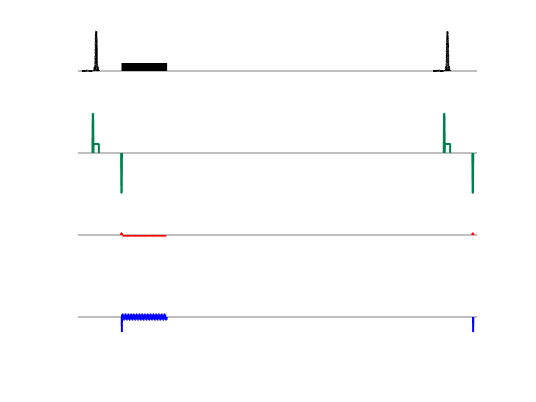

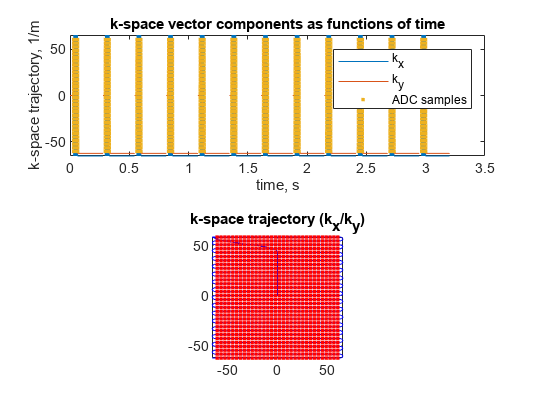

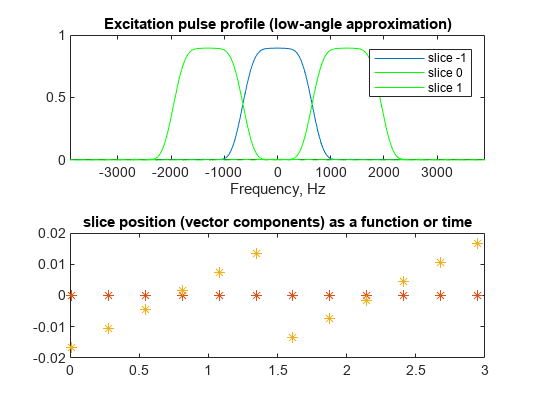

% First we have to define the main set of paramters of the sequence
SeqParam = struct('TE', 35e-3,'TR', 3, ...                  % TE and TR - units in seconds
                    'Nx', 32,'Ny', 32,'Nz', 12,...          % matrix size it will be generating
                    'FOV', 0.256,'sliceThickness',3e-3,'sliceGap',0,... % Field of view and slice thickness (units in meters)
                    'flipAngle',90,'timeBwProduct',5.2,...  % Some properties associated with the Excitatoin RF pulse 
                    'readoutTime',10e-4,...                 % duration of the readout gradient number of echo times
                    'ME',1,'iPat',1);


Show.SequenceDiagram = 1;
Show.SliceProfile = 1;
Show.KspaceTimeCourse = 1;
Show.KspaceCoverage = 1;


% Create EPI sequence for a Skyra system

%writeEpiRS_HandsOn(SeqParam,sysSkyra,Show);
writeEPIME_HandsOn(SeqParam,sysSkyra,Show);

%writeEpiRS_HandsOn(SeqParam,sysSkyra,Show);

% First figure
% look at the first sequence diagram: can you identify:
%- Slice selective gradient
%- EPI readout gradient 
%- the phase encoding blips
%
% Second figure
% - first plot shows the k-space trajectory as a function of time - see
% that k-space center in only crossed at the center of the echo train 
% - second plot shows how k-space is covered over time - blue line showing
% the trajectory of how it covers the k-space, red dots show the actual
% sampling
%
%
% Third figure
% - slice profile of three consecutive slices
% - Interleaved order in which slices are acquired in a Typical Experiment 
% - Why do you think an interleaved slice order acquisition is typically used?




Exercise 14 Try to make the previous sequence have a 2 mm in plane resolution 

Res = 2e-3; % resolution in meters

% if you keep the FOV unchanged, you have to change the number of readouts in each direction 
% update the relevant parameters
SeqParam.Nx = round(SeqParam.FOV/Res);
SeqParam.Ny = round(SeqParam.FOV/Res)

SeqParam = struct with fields:
                TE: 0.0350
                TR: 3
                Nx: 128
                Ny: 128
                Nz: 12
               FOV: 0.2560
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
       readoutTime: 1.0000e-03
                ME: 1
              iPat: 1


Your provided TE was too short, increased to 0.069065


SeqParamOut = struct with fields:
                TE: 0.0691
                TR: 3
                Nx: 128
                Ny: 128
                Nz: 12
               FOV: 0.2560
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
       readoutTime: 1.0000e-03
                ME: 1
              iPat: 1


Timing check passed successfully


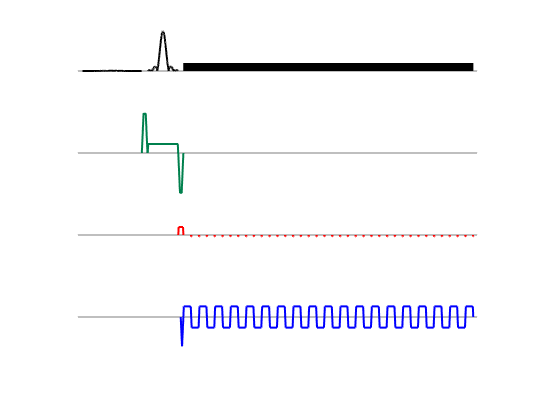

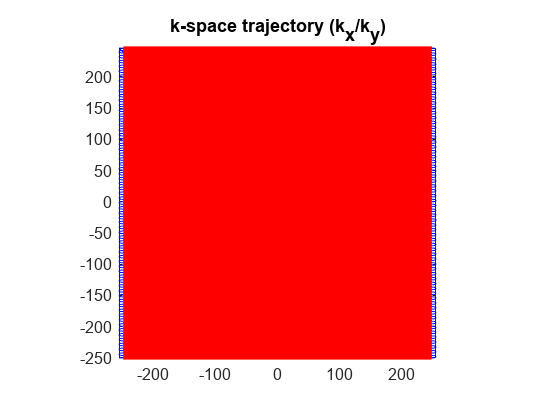


Show.SliceProfile = 0;
Show.KspaceTimeCourse = 0;

SeqParamOut= writeEPIME_HandsOn(SeqParam,sysSkyra,Show);

What are the main differences you observe in respect to the previous sequence?

Note that there is no dead between slice excitation and the EPI train, and there was an output error stating that the minimum echo time was not achievable, and a longer echo time was used! See the output SeqParamOut

Many strategies to achieve your aimed image resolution

display('Trying to Get that Protocol!')

Trying to Get that Protocol!


Your provided TE was too short, increased to 0.069065


SeqParamOut = struct with fields:
                TE: 0.0691
                TR: 3
                Nx: 128
                Ny: 128
                Nz: 12
               FOV: 0.2560
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
       readoutTime: 1.0000e-03
                ME: 1
              iPat: 1


Timing check passed successfully


SeqParamOut = struct with fields:
                TE: 0.0691
                TR: 3
                Nx: 128
                Ny: 128
                Nz: 12
               FOV: 0.2560
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
       readoutTime: 1.0000e-03
                ME: 1
              iPat: 1


SeqParam.readoutTime = 0.001;      % in seconds
SeqParam.TE= 0.035;                % in seconds
sys =sysSkyra;                     % choose the MR system you want to use
SeqParam.iPat = 1;             % change the in plane parallel imaging acceleration Factor

% Create EPI sequence for the options above
% first using the Skyra system, TE =35ms and 2mm inplane resolution
%   (i) try reducing the readout time from 1ms in
%       steps of 0.1ms as short as possible, 
%       anything interesting happening on the Readout Gradient?
% were you able to achieve the aimed Echo time using the Siemens 3T Skyra?
%   (ii) try changing the in plane acceleration (iPat), you can now probably
%   achieve the aimed protocol even without too much acceleration...
%   (iii) return to iPat 1, change the gradient system, any success?

SeqParamOut = writeEPIME_HandsOn(SeqParam,sys,Show)

Exercise 15

Acquiring a Multi-echo fMRI dataset

% now we will try to be less ambitious in the resolution
Res = 2.5e-3; % resolution in meters
%

% Standard set of parameters
SeqParam = struct('TE', [13 35 57]*1e-3,'TR', 3, ...                  % TE and TR - units in seconds
                    'Nz', 12,...          % matrix size it will be generating
                    'sliceThickness',3e-3,'sliceGap',0,... % Field of view and slice thickness (units in meters)
                    'flipAngle',90,'timeBwProduct',5.2)  % Some properties associated with the Excitatoin RF pulse 

SeqParam = struct with fields:
                TE: [0.0130 0.0350 0.0570]
                TR: 3
                Nz: 12
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000


% Resolution             
SeqParam.FOV =210e-3; % we want our FOV to just about fit the head
SeqParam.Nx = round(SeqParam.FOV/Res);
SeqParam.Ny = round(SeqParam.FOV/Res);

% parameters to be adapted to obtain the aimed range of 
SeqParam.readoutTime = 0.00045;      % in seconds
sys =sysSkyra;                     % choose the MR system you want to use
SeqParam.iPat = 2;             % change the in plane parallel imaging acceleration Factor
SeqParam.ME = 3           % change the in plane parallel imaging acceleration Factor

SeqParam = struct with fields:
                TE: [0.0130 0.0350 0.0570]
                TR: 3
                Nz: 12
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
               FOV: 0.2100
                Nx: 84
                Ny: 84
       readoutTime: 4.5000e-04
              iPat: 2
                ME: 3


Your provided TE was too short, increased to 0.01315


SeqParamOut = struct with fields:
                TE: [0.0131 0.0358 0.0585]
                TR: 3
                Nz: 12
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
               FOV: 0.2100
                Nx: 84
                Ny: 84
       readoutTime: 4.5000e-04
              iPat: 2
                ME: 3


Timing check passed successfully


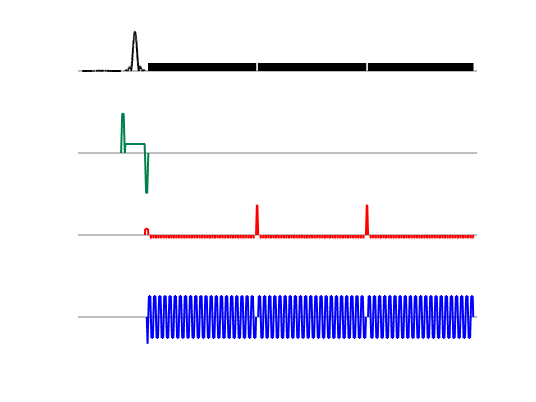

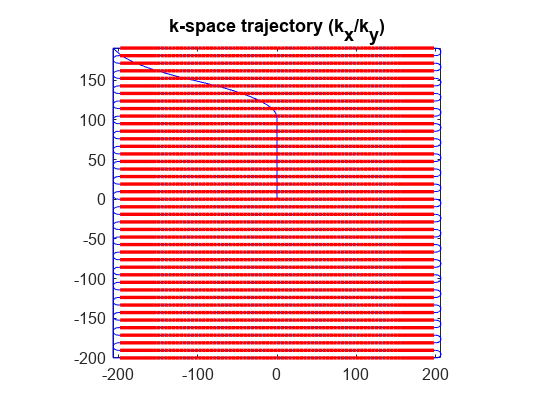

SeqParamOut = struct with fields:
                TE: [0.0131 0.0358 0.0585]
                TR: 3
                Nz: 12
    sliceThickness: 0.0030
          sliceGap: 0
         flipAngle: 90
     timeBwProduct: 5.2000
               FOV: 0.2100
                Nx: 84
                Ny: 84
       readoutTime: 4.5000e-04
              iPat: 2
                ME: 3



Show.KspaceTimeCourse = 0;

SeqParamOut= writeEPIME_HandsOn(SeqParam,sys,Show)


% check the sequence trajectory, what is the difference in respect to the
% single echo EPI ? Why do you have two large gradient blips in the Phase
% encoding gradient waveform? examine the k-space trajectory by zooming out...
% What would be the advantage of using the Stronger gradient system in such a
% sequence? 
% Change system from Skyra to NextGeneration, and try to achieve similar
% echo times can this be achieved without
